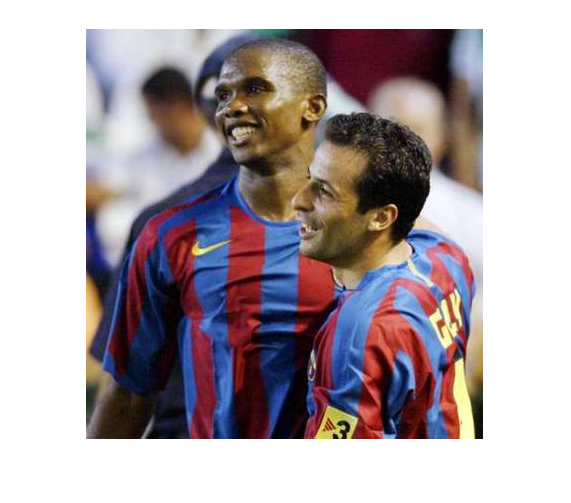

im = imread('soccer\barcelona\34.jpg');
im2 = imread('soccer\barcelona\35.jpg');

imshow(im);

tam = 50;
[HModelHist, SModelHist] = getHists(im, tam);
[HModelHist2, SModelHist2] = getHists(im2, tam);

HModelHist = (HModelHist + HModelHist2)/2;
SModelHist = (SModelHist + SModelHist2)/2;

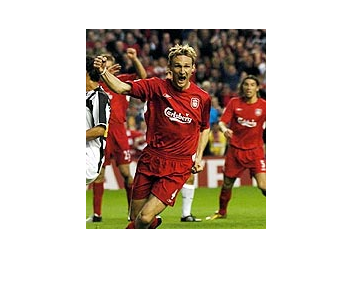

imtest = imread('soccer\liverpool\05.jpg');
imshow(imtest)

cercaEquip(HModelHist, SModelHist, imtest) 

errH = 4.3570e+03

errS = 1.8602e+03

ans = logical
   0


function result = cercaEquip(HModelHist, SModelHist, im)
    
    [x, y] = size(im(:,:,1));
    
    r = im(:,:,1);
    g = im(:,:,2);
    b = im(:,:,3);
    
    I = (double(r) + double(g) + double(b))/3;
    red = double(r)./I;
    gre = double(g)./I;
    blu = double(b)./I;
    
    imcat = cat(3, red, gre, blu);
    [c, f] = colCenter(imcat, 1, 3);
    
    result = false;
    tam = 50;
    fma = f+tam;
    fmi = f-tam;
    cmi = c-tam;
    cma = c+tam;
    
    if((f+tam)> x)
        fma = x;
        fmi = x-(tam*2);
        if(fmi < 1) 
            fmi = 1;
        end
    elseif((f-tam) < 1)
        fmi = 1;
        fma = 1+(tam*2);
        if(fma > x) 
            fma = x;
        end
    end
    
    if((c+tam)> y)
        cma = y;
        cmi = y-(tam*2);
        if(cmi < 1) 
            cmi = 1;
        end
    elseif((c-tam) < 1)
        cmi = 1;
        cma = 1+(tam*2);
        if(cma > y) 
            cma = y;
        end
    end
    
    
    im = rgb2hsv(im);
    h = im(:,:,1);
    s = im(:,:,2);
    v = im(:,:,3);
    im = cat(3, h, s, v);
    
    im(:,:,1) = uint8(normalize(im(:,:,1), 'range')*360); %H
    im(:,:,2) = uint8(normalize(im(:,:,2), 'range')*100); %S
    
    HImgeHist = colorHistogram(fmi, fma, cmi, cma, 1, im);
    SImgeHist = SaturationHistogram(fmi, fma, cmi, cma, 2, im);
            
    errH = distChiSq(HImgeHist, HModelHist)
    errS = distChiSq(SImgeHist, SModelHist)
    
    
    res = 0;
    
    if (errH < 2500 && errS < 2500)
        res = res + 3;
    end
    
    if (errH > 3000 && errS > 2900)
        res = res -3;
    end
    
    if ((errH + errS) < 5800)
        res = res + 4;
    else 
        res = res - 2;
    end
    
    
    if (errH > 2800)
        res = res - 2;
    end
    
    if (errH < 2800)
        if (errH < 1900)
            res = res + 4;
        else
        res = res + 2;
        end
    end
    
    if (errS < 2000)
        if (errS < 1200)
            res = res + 4;
        else
        res = res + 3;
        end
    end
    
   
    
    if (res > 0)
        result = true;
    else
        result = false;
    end
    
end

function [c, f] = centerr(im, d)

    [x,y] = size(im(:,:,1));
    res = zeros(1,y);
    max = 0;
    for i = [1:y]
        res(1, i) = nansum(im(:,i,d));
        if (res(1,i) > max)
            c = i;
            max = res(1, i);
        end
    end
    max = 0;
    res = zeros(1,x);
    for i = [1:x]
        res(1, i) = nansum(im(i,:,d));
        if (res(1,i) > max)
            f = i;
            max = res(1, i);
        end
    end
end

function [c, f] = colCenter(im, d1, d2)

    [c, f] = centerr(im, d1);
    [cc, ff] = centerr(im, d2);
    
    c = uint16((cc+c)/2);
    f = uint16((ff+f)/2);

end

function [hHist, sHist] = getHists(im, tam)
       

    r = im(:,:,1);
    g = im(:,:,2);
    b = im(:,:,3);
    
    I = (double(r) + double(g) + double(b))/3;
    red = double(r)./I;
    gre = double(g)./I;
    blu = double(b)./I;
    
    imcat = cat(3, red, gre, blu);
    
    [c, f] = colCenter(imcat, 1, 3);
    %tam = 75;
    
    im = rgb2hsv(im);
    h = im(:,:,1);
    s = im(:,:,2);
    v = im(:,:,3);
    im = cat(3, h, s, v);
    
    im(:,:,2) = uint8(normalize(im(:,:,2), 'range')*100); %S
    im(:,:,1) = uint8(normalize(im(:,:,1), 'range')*360); %H
    
    
    hHist = colorHistogram(f-tam, f+tam, c-tam, c+tam, 1, im);
    sHist = SaturationHistogram(f-tam, f+tam, c-tam, c+tam, 2, im);

end

function model = colorHistogram(xini, xfin, yini, yfin, color, im)
    model = zeros(1, 91);
    for i = [yini:yfin]
        for j = [xini:xfin]
            model(1, uint8(im(j, i, color)/4)+1) = model(1, uint8(im(j, i, color)/4)+1) + 1;
        end
    end
    %bar(model);
end

function model = SaturationHistogram(xini, xfin, yini, yfin, color, im)
    model = zeros(1, 26);
    for i = [yini:yfin]
        for j = [xini:xfin]
            model(1, uint8(im(j, i, color)/4)+1) = model(1, uint8(im(j, i, color)/4)+1) + 1;
        end
    end
    %bar(model);
end

function D = distChiSq( X, Y )

    m = size(X,1);  
    n = size(Y,1);
    mOnes = ones(1,m); 
    D = zeros(m,n);
    
    for i=1:n
      yi = Y(i,:);  
      yiRep = yi( mOnes, : );
      s = yiRep + X;    
      d = yiRep - X;
      D(:,i) = sum( d.^2 ./ (s+eps), 2 );
    end
    D = D/2;
end
